%% Plots all flow, pressure, etc values on network map for a specific time step.
% This function contains:
%   Load a network.
%   Hydraulic analysis using ENepanet binary file.
%   Get node and link info.
%   Set custom offset for text.
%   Get plot axes.
%   Plot flow values on map.
%   Plot pressure values on map.
%   Unload library.

%%
% Clear
clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.



% Load a network.
d = epanet('Threenode-cl-2.inp');

EPANET loaded sucessfuly.
Loading File "Threenode-cl-2.inp"...
Input File "Threenode-cl-2.inp" loaded sucessfuly.


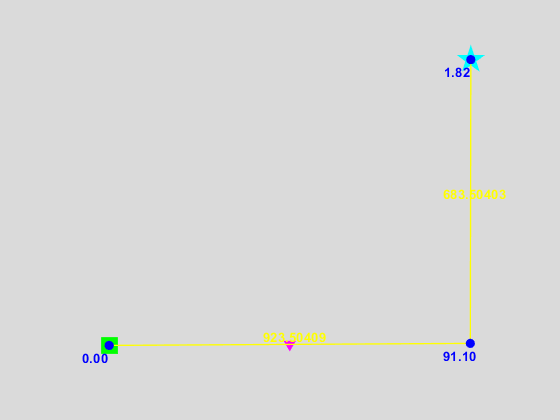


% Hydraulic analysis using ENepanet binary file.
% (This function ignore events)
t_h = 12; % set time to 12 hours
d.setTimeSimulationDuration(t_h*60*60);
hyd_res = d.getComputedTimeSeries;

% Get node and link info.
% times = hyd_res.Time; % get time stamps
color = 'y'; % choose color
nodenameid = d.getNodeNameID; % get node IDs
linknameid = d.getLinkNameID; % get link IDs
nodesconnlinks = d.getNodesConnectingLinksID; % get node connectivity
nodecoords = d.getNodeCoordinates; % get node coordinates
  
% Set custom offset for text.
x = nodecoords{1};
y = nodecoords{2};
min_coorx = min(x);
min_coory = min(y);
max_coorx = max(x);
max_coory = max(y);
xsenoff = (max_coorx - min_coorx) * 0.075;
ysenoff = (max_coory - min_coory) * 0.03;

% Get plot axes.
fig = d.plot('legend', 'hide');
format long g

% Plot flow values on map.
time_step = 12;
flow = hyd_res.Flow(time_step,:);
fontweight = 'bold';
fontsize = 10;
for i = d.getLinkIndex
    value = flow(i);    
    FromNode=strfind(strcmp(nodesconnlinks(i, 1), nodenameid), 1);
    ToNode=strfind(strcmp(nodesconnlinks(i, 2), nodenameid), 1);

    if FromNode
        x1 = double(nodecoords{1}(FromNode));
        y1 = double(nodecoords{2}(FromNode));
    end
    if ToNode
        x2 = double(nodecoords{1}(ToNode));
        y2 = double(nodecoords{2}(ToNode));
    end
    line([x1 nodecoords{3}{i} x2], [y1 nodecoords{4}{i} y2], 'LineWidth', 1, 'Color', color, 'Parent', fig);
    text((x1+x2)/2-xsenoff, (y1+y2)/2+ysenoff, num2str(value, '%.5f'), 'FontWeight', fontweight, 'Fontsize', fontsize, 'color', color)
end

% Plot pressure values on map.
time_step = 12;
pressure = hyd_res.Pressure(time_step,:);
ysenoff = (max_coory - min_coory) * (-0.04);
color = 'b';
fontweight = 'bold';
fontsize = 10;
for i = d.getNodeIndex
    value = pressure(i);
    coor = d.getNodeCoordinates(i);
    x = coor(1); 
    y = coor(2);
    plot(x, y, 'o', 'LineWidth', 2, 'MarkerEdgeColor', color, 'MarkerFaceColor', color, 'MarkerSize', 5);
    text(x-xsenoff, y+ysenoff, num2str(value, '%.2f'), 'FontWeight', fontweight, 'Fontsize', fontsize, 'color', color)
end


% Unload library.
d.unload

EPANET Class is unloaded
